format long

current_point = [4.151779 3.910639 8.218826];
closest_point = [4.255657 7.538139 5.896898];

segment_p1 = [10 10 10];

relative = current_point - segment_p1

relative =   -5.848221000000000  -6.089361000000000  -1.781174000000000


norm(relative)

ans =    8.628707149477146


unit_segment = [-0.768350 -0.329293 -0.548821];
closest_point_relative = closest_point - segment_p1

closest_point_relative =   -5.744343000000000  -2.461861000000000  -4.103102000000000


norm(closest_point_relative)

ans =    7.476207735702238



orthogonal_vector = relative - closest_point_relative

orthogonal_vector =   -0.103878000000000  -3.627500000000000   2.321928000000000


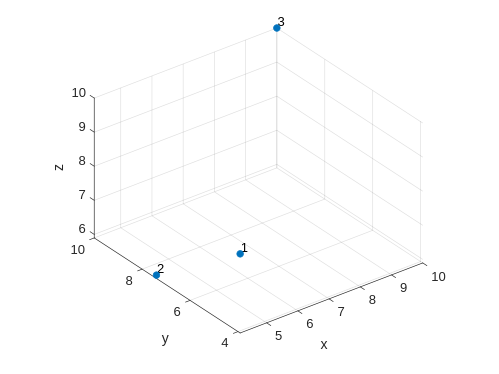

orthogonal_versor = orthogonal_vector ./ norm(orthogonal_vector)

pts.x = [current_point(1) closest_point(1) segment_p1(1)];
pts.y = [current_point(2) closest_point(2) segment_p1(2)];
pts.z = [current_point(3) closest_point(3) segment_p1(3)];

figure
plot3Dpoints(pts, 'o')
hold on